% test run on eigenmodes of Amundsen glacier shelf

% need this to generate grid g
run("illapel_amundsen_ice.m")

% where mat_A_B_q.mat is
% the generated file containing matrices A,B; vector q0
addpath('../Amundsen/')
% already stored the wanted evals/evecs from GEP
load('mat_A_B_q.mat')

%ecount = 5; % set to 10 or other number

Sigma = ["largestabs","smallestabs","largestreal","smallestreal"];
Size = length(q0)/2;

ecount = 5;
[V,D] = eigs(B,A,ecount,"smallestabs")

sigma = 'smallestabs'

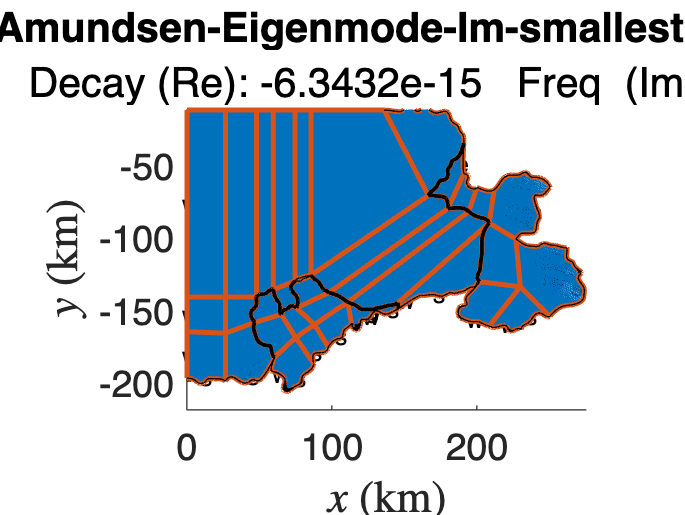

sigma = 'smallestabs'

sigma = 'smallestabs'

sigma = 'smallestabs'

sigma = 'smallestabs'

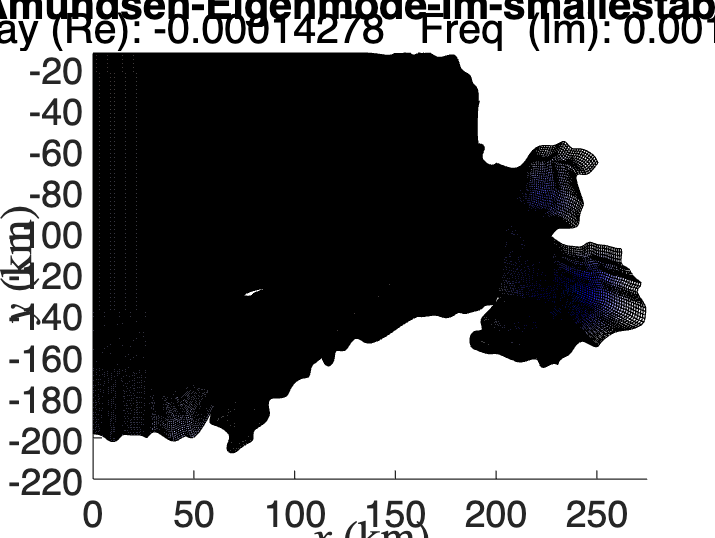

W = V(1:Size,:);

for i = 1:ecount
    w = W(:,i);
    
    % normalize the eigenvector
    w = w / max(abs(w));
    

    %sigma = convertStringsToChars(Sigma(j));
    sigma = 'smallestabs'
    ptitle = ['Amundsen-Eigenmode-Im-',sigma,num2str(i)];
    %figure(i)
    
    
    figure(i)
    hold on
    cmap
    %clim([-1 1]);
    for k = 1:length(g_ice.boundaryGroups.FR)
        free_coord = g.getBoundary(g_ice.boundaryGroups.FR(k));
        p1 = plot3(free_coord(:, 1), free_coord(:, 2), 1000 + 0*free_coord(:, 1), 'black-', 'LineWidth', 1.5);
        uistack(p1, 'top')                        
        hold on
    end
    for k = 1:length(g.boundaryGroups.R)
        reflectN = g.getBoundary(g.boundaryGroups.R(k));
        p2 = plot3(reflectN(:, 1), reflectN(:, 2), 1000 + 0*reflectN(:, 1), 'black-', 'LineWidth', 0.5);
        uistack(p2, 'top')
        hold on
    end
%     
    
    xlabel('$x$ (km)', 'Interpreter', 'latex', 'FontSize', 18)
    ylabel('$y$ (km)', 'Interpreter', 'latex', 'FontSize', 18)
    xlim([plot_details.left, plot_details.right])
    ylim([plot_details.bottom, plot_details.top])
% 
     ph = multiblock.Surface(g, real(w));
     caxis([plot_details.caxis_low, plot_details.caxis_up])

    c = colorbar;
    c.Label.String = 'Wave height, $w$ (m)';
    c.Label.Interpreter = 'latex';
    c.Label.FontSize = 20;
    ph.set('LineStyle', 'none');
    ph.set('FaceColor', 'interp');

    % this is just exporting, everythign above is identical
    freqtitle = ['Decay (Re): ',num2str(real(D(i,i))),...
        '   Freq  (Im): ',num2str(imag(D(i,i)))];
    title(ptitle)
    subtitle(freqtitle)
    ax = gcf;
    picfilename = [ptitle,'.png'];
    exportgraphics(ax,picfilename);
end

% [Vcom, Dcom] = eig(B,A)